# OpenAI Images

[https://beta.openai.com/docs/guides/images/introduction](https://beta.openai.com/docs/guides/images/introduction)

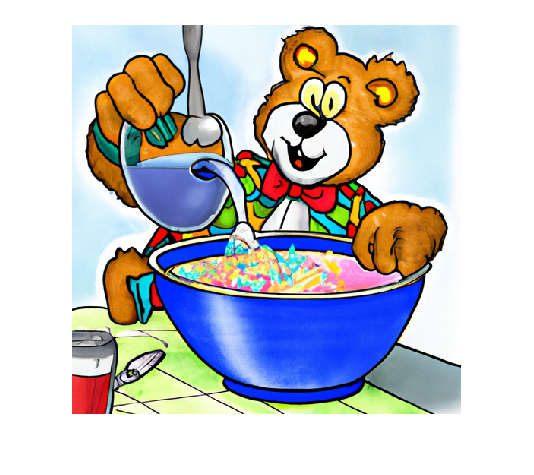

## Set-up Python

pyenv(Version="..\env\Scripts\python.exe",ExecutionMode="OutOfProcess")

## Set-up OpenAI

Save OpenAI key in secrets.toml file

pythonCode = ["import tomli;"; ...
    "f = open('secrets.toml','rb')"; ...
    "toml_dict = tomli.load(f)"; ...
    "key = toml_dict['OPEN_AI_KEY']"; ...
    "f.close()"];
OPEN_AI_KEY = pyrun(pythonCode,"key");
% OPEN_AI_KEY = string(OPEN_AI_KEY);

Or enter the API key directly in the notebook (don't share your key with others):

% OPEN_AI_KEY = "";

Set-up the API with the key:

pyrun("import openai;openai.api_key = OPEN_AI_KEY",OPEN_AI_KEY = OPEN_AI_KEY)

## Image Generation

[https://beta.openai.com/docs/guides/images/generations](https://beta.openai.com/docs/guides/images/generations)

p = "Teddy bears mixing sparkling chemicals as mad scientists a 1990s Saturday morning cartoon";
n = 1;
s = "512x512";
pythonCode = "import openai; response = openai.Image.create(prompt=p,n=int(n),size=s);image_url = response['data'][0]['url']";
image_url = pyrun(pythonCode,"image_url",p=p,n=n,s=s)

image_url =   Python str with no properties.

    https://oaidalleapiprodscus.blob.core.windows.net/private/org-MULpNcghJDQrcsR4f2hYHcyI/user-poiBzg7wGX385TjCQqGSwSms/img-xvzJXnt6xv1g0vcZHZ6s1RT5.png?st=2022-12-05T12%3A24%3A23Z&se=2022-12-05T14%3A24%3A23Z&sp=r&sv=2021-08-06&sr=b&rscd=inline&rsct=image/png&skoid=6aaadede-4fb3-4698-a8f6-684d7786b067&sktid=a48cca56-e6da-484e-a814-9c849652bcb3&skt=2022-12-05T13%3A24%3A23Z&ske=2022-12-06T13%3A24%3A23Z&sks=b&skv=2021-08-06&sig=n3h/kiSwm50wrvrSHOSSGYo9Gb%2BYPdgjHftufZ1E6O4%3D


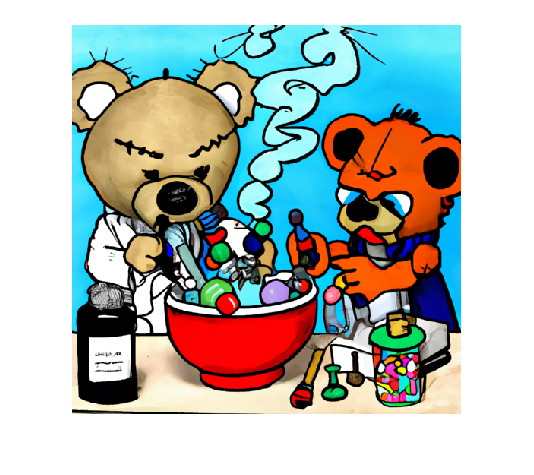

im = imread(string(image_url));
imshow(im)